# Population logistic growth model

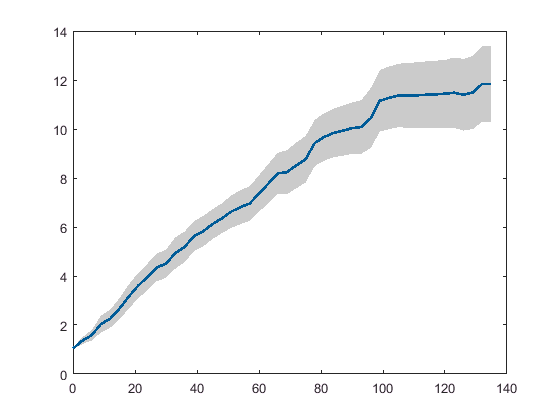

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')

t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);
P = M(13).Mean(t0:tend);
SEM = M(13).SEM(t0:tend);
figure
p1 = plot(t1,P,'LineWidth',2);
hold on
er1 = P+SEM;
er2 = P-SEM;
p2 = fill([t1;flip(t1)],[er1;flip(er2)],'k','LineStyle','none');
alpha(p2,0.2)

Fit Verhulst model

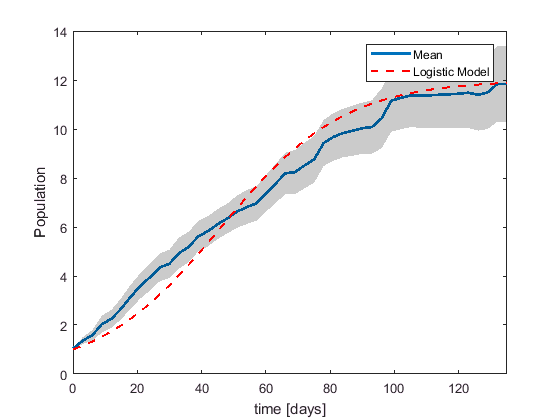

N = @(N0,Ns,a,t) Ns./(1+((Ns./N0)-1).*exp(-a.*t));
N0=1;
Ns=12;
hold on
p3 = plot(t1,N(N0,Ns,0.052,t1),'--r','LineWidth',1.5);
xlim([0 135])
xlabel('time [days]')
ylabel('Population')
legend([p1 p3],{'Mean','Logistic Model'})


Verhulst

Verhulst =      General model:
     Verhulst(t) = Ns./(1+((Ns./1)-1).*exp(-a.*t))
     Coefficients (with 95% confidence bounds):
       Ns =       11.47  (11.13, 11.81)
       a =     0.05216  (0.04967, 0.05464)

goodness

goodness = struct with fields:
           sse: 13.5360
       rsquare: 0.9745
           dfe: 44
    adjrsquare: 0.9739
          rmse: 0.5546